clc,clear,close all
syms x t

%------------设置------------%
f = sqrt(1+x^2);   % 逼近函数
n = 2;          % 拟合次数
a = 0;          % 逼近区间
b = 1;          % 逼近区间 [a,b]

%-------------核心代码--------%  
% 先做区间变换

g = subs(f,x,(b-a)/2*t+(b+a)/2);
A = zeros(n+1,1);
for i = 0:n
    A(i+1) = (2*i+1)/2*int(g*P(i),t,-1,1);
end

S = 0;
for i = 0:n
    S = S + A(i+1)*P(i);
end
vpa(S,5)

$$ans = 0.089172\,t^{2}+0.21347\,t+1.1181$$

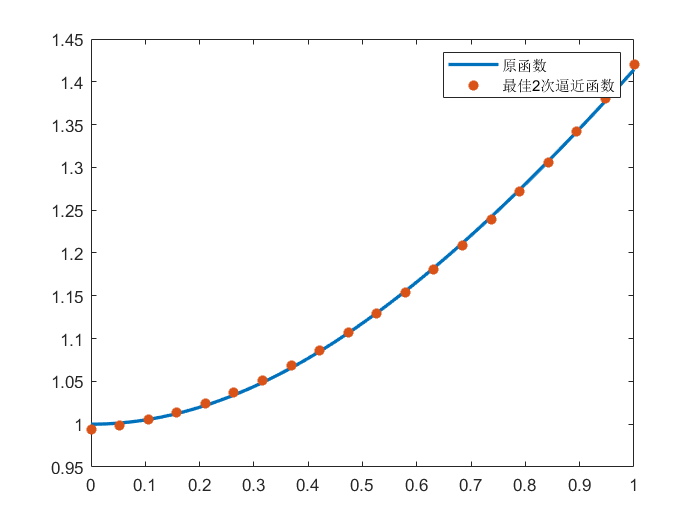

S = vpa(collect(subs(S,t,1/(b-a)*(2*x-a-b))),4);
%----------结果输出---------%
% 作图
xx = a:0.01:b;
yy = vpa(subs(f,x,xx));
xx_1 = linspace(a,b,20);
yy_2 = vpa(subs(S,x,xx_1));
plot(xx,yy,xx_1,yy_2,'*','linewidth',2);
legend('原函数',['最佳',num2str(n),'次逼近函数'])

% 输出函数
disp(['最佳',num2str(n),'次逼近函数为'])

最佳2次逼近函数为


disp(S)

$$0.3567\,x^{2}+0.07026\,x+0.9938$$

function P = P(n)
% 勒让德多项式
    syms t
    P = collect(1/(2^n*factorial(n))*diff((t^2-1)^n,t,n));
end